# Lab - Initial value problems 3

**Topics: **Stiff systems

## Initial values


$$y_1 \left(0\right)=\frac{{\textrm{dy}}_1 }{\textrm{dt}}\left(0\right)=1$$


Y0 = [1 1];

## ode45 mu = 1, t = 0 to 60

mu = 1;
[t, y] = ode45(@vanDerPol, [0 60], Y0, [], mu);

t =          0
    0.0502
    0.1005
    0.1507
    0.2010
    0.3377
    0.4744
    0.6111
    0.7478
    0.8786


y =     1.0000    1.0000
    1.0489    0.9461
    1.0949    0.8854
    1.1378    0.8187
    1.1771    0.7472
    1.2650    0.5370
    1.3235    0.3200
    1.3530    0.1116
    1.3551   -0.0772
    1.3344   -0.2364


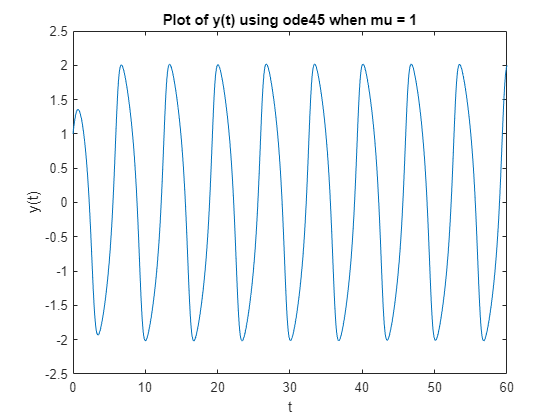


plot(t, y(:,1))
xlabel t
ylabel y(t)
title("Plot of y(t) using ode45 when mu = 1")

## ode45 mu = 1000, t = 0 to 6000

mu = 1000;
% ode45(@vanDerPol, [0 6000], Y0, [], mu)

## ode23s mu = 1000, t = 0 to 6000

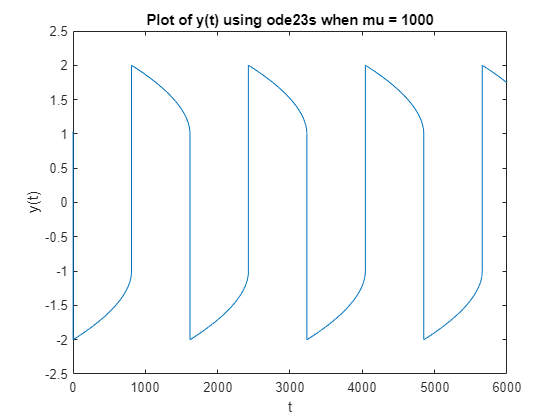

[t, y] = ode23s(@vanDerPol, [0 6000], Y0, [], mu);
plot(t, y(:,1))
xlabel t
ylabel y(t)
title("Plot of y(t) using ode23s when mu = 1000")

## Helper functions


$$\frac{d}{\textrm{dt}}\left\lbrack Y\right\rbrack =\left\lbrack \begin{array}{c}
Y\left(2\right)\\
\mu \left(1-{Y\left(1\right)}^2 \right)Y\left(2\right)-Y\left(1\right)
\end{array}\right\rbrack$$


function dY = vanDerPol(t, Y, mu)
dY = [Y(2);
      mu*(1-Y(1)^2)*Y(2)-Y(1)];
end